hcn = 12; %number of HC subjects
hcss = 2; %number of sessions for HC subjects
msn = 12; %number of MS patients
msss = 5; %number of sessions for MS patients


LOAD DATA OF HC SESSIONS 1-2 INTO CELL ARRAY HCs

%load healthy controls session 1 and 2
dataFolder = "C:\Users\damis\Google Drive\ETH\Master\2 semester\Translational Neuromodelling\Final Project\Data_preprocessed\";
HCs = cell(hcss,hcn);
for i = 1:hcn
    dir1 = sprintf("HC\\Subject%03d\\ROI_Subject%03d_Session001.mat",i,i);
    dir2 = sprintf("HC\\Subject%03d\\ROI_Subject%03d_Session002_new.mat",i,i);
    m1 = matfile(join([dataFolder,dir1],""));
    m2 = matfile(join([dataFolder,dir2],""));
    HCs{1,i} = m1.data;
    HCs{2,i} = m2.data;
end


RUN ONLY ONE TIME TO CHANGE THE NAMES OF THE FILES FOR MS

dataFolder = "C:\Users\damis\Google Drive\ETH\Master\2 semester\Translational Neuromodelling\Final Project\Data_preprocessed\";
%change name of files so that they make sense buoy
for k=1:msn
for i= 1:msss
    oldfilename = sprintf("MS\\Pat%03d\\ROI_Subject%03d_Session001.mat",k,i);
    newfilename = sprintf("MS\\Pat%03d\\ROI_pat%03d_Session%03d.mat",k,k,i);
    if ~isequal(newfilename, oldfilename)
        movefile(join([dataFolder,oldfilename],""),join([dataFolder,newfilename],""))
    end
    
end
end

LOAD MS PATIENTS DATA SESSIONS 1-5 INTO CELL ARRAY MSs

%LOAD MS PATIENTS SESSIONS 1-5
MSs = cell(msss,msn);
dataFolder = "C:\Users\damis\Google Drive\ETH\Master\2 semester\Translational Neuromodelling\Final Project\Data_preprocessed\";
for k=1:msn
    for i=1:msss
        path = sprintf("MS\\Pat%03d\\ROI_pat%03d_Session%03d.mat",k,k,i);
        mfile = matfile(join([dataFolder,path],""));
        MSs{i,k} = mfile.data;
    end
end

RUN TAPAS rDCM ESTIMATION FOR HCs, FULLY CONNECTED REGIONS

%define fully connectected DCM structure with parameters, data inserted
%in the loop
DCMfc.a = ones(7);
DCMfc.b = [];
DCMfc.c = [];
DCMfc.d = [];
DCMfc.options.nonlinear = 0; 
DCMfc.options.two_state = 0;
DCMfc.options.stochastic = 0;
DCMfc.options.centre = 1;
DCMfc.options.induced = 1;
DCMfc.n = 7;
DCMfc.Y.dt = 3;

HCconnections = cell(hcss,hcn); %CELL ARRAY WITH CONNECTIONS FOR EACH SUB AND SESS

for k = 1:hcn
    for i = 1:hcss
       DCMfc.Y.y = HCs{i,k};
       [output] = tapas_rdcm_estimate(DCMfc, 'r', [], 2);
       HCconnections{i,k} = output;
    end
end
save connectionsHC.mat HCconnections


RUN TAPAS rDCM FOR MS PATIENTS, FULLY CONNECTED

%define fully connectected DCM structure with parameters, data inserted
%in the loop
DCMfc.a = ones(7);
DCMfc.b = [];
DCMfc.c = [];
DCMfc.d = [];
DCMfc.options.nonlinear = 0; 
DCMfc.options.two_state = 0;
DCMfc.options.stochastic = 0;
DCMfc.options.centre = 1;
DCMfc.options.induced = 1;
DCMfc.n = 7;
DCMfc.Y.dt = 3;

MSconnections_ns = cell(msss, msn);

for k = 1:msn
    for i = 1:msss
       k,i
       DCMfc.Y.y = MSs{i,k};
       [output] = tapas_rdcm_estimate(DCMfc, 'r', [], 1);
       MSconnections_ns{i,k} = output;
    end
end

save ns_connectionsMS.mat MSconnections_ns

%get A matrices and node strengths
HCA_mat = cell(hcss,hcn); %carray with all A-matrices for HC
MSA_mat = cell(msss,msn); %carray with all A-matrics for MS pat
HCnode_strengths = cell(hcss,hcn);
MSnode_strengths = cell(msss,msn); 
HCexp = cell(hcss,hcn);
MSexp = cell(msss,msn);



for row=1:hcss
    for column=1:hcn
        HCA_mat{row,column} = HCconnections{row,column}.Ep.A;
        HCnode_strengths{row,column} = sum(HCA_mat{row,column},1) + sum(HCA_mat{row,column},2)';
    end
end

A = ones(7) - eye(7);
for row=1:msss
    for column=1:msn
    MSA_mat{row,column} = MSconnections_ns{row,column}.Ep.A;
    a = exp(-MSA_mat{row,column});
    %MSexp{row,column} = exp(a);
    %MSnode_strengths{row,column} = sum((A.*a),1) + sum(A.*a,2)';
    MSnode_strengths{row,column} = sum(a,1) + sum(a,2)';
    end
end

%get mean (over patients) of node strength for each region/session 
MS_ns_mean = cell(msss,1);
HC_ns_mean =  cell(hcss,1);

for i=1:msss
    sum = 0;
    for m = 1:msn
        sum = sum + MSnode_strengths{i,m};
    end
    MS_ns_mean{i} = sum / msn;
end


for i=1:hcss
    sum = 0;
    for m = 1:hcn
        sum = sum + HCnode_strengths{i,m};
    end
    HC_ns_mean{i} = sum / hcn;
end

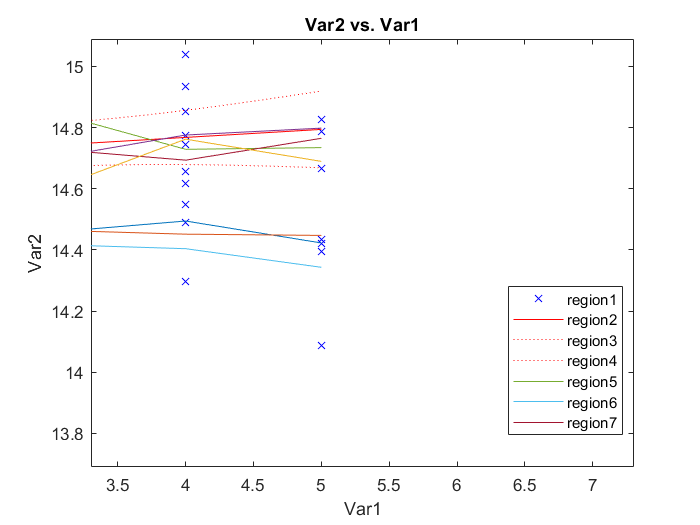

sessions = linspace(1,5,5);

figure(1); hold on;
plot(sessions,[MS_ns_mean{1,1}(1),MS_ns_mean{2,1}(1),MS_ns_mean{3,1}(1),MS_ns_mean{4,1}(1),MS_ns_mean{5,1}(1)],'-');
plot(sessions,[MS_ns_mean{1,1}(2),MS_ns_mean{2,1}(2),MS_ns_mean{3,1}(2),MS_ns_mean{4,1}(2),MS_ns_mean{5,1}(2)],'-');
plot(sessions,[MS_ns_mean{1,1}(3),MS_ns_mean{2,1}(3),MS_ns_mean{3,1}(3),MS_ns_mean{4,1}(3),MS_ns_mean{5,1}(3)],'-');
plot(sessions,[MS_ns_mean{1,1}(4),MS_ns_mean{2,1}(4),MS_ns_mean{3,1}(4),MS_ns_mean{4,1}(4),MS_ns_mean{5,1}(4)],'-');
plot(sessions,[MS_ns_mean{1,1}(5),MS_ns_mean{2,1}(5),MS_ns_mean{3,1}(5),MS_ns_mean{4,1}(5),MS_ns_mean{5,1}(5)],'-');
plot(sessions,[MS_ns_mean{1,1}(6),MS_ns_mean{2,1}(6),MS_ns_mean{3,1}(6),MS_ns_mean{4,1}(6),MS_ns_mean{5,1}(6)],'-');
plot(sessions,[MS_ns_mean{1,1}(7),MS_ns_mean{2,1}(7),MS_ns_mean{3,1}(7),MS_ns_mean{4,1}(7),MS_ns_mean{5,1}(7)],'-');
    legend('region1','region2','region3','region4','region5','region6','region7');

t = ones(1,12);
for i = 2:5
    t = [t, ones(1,12)*i]
end

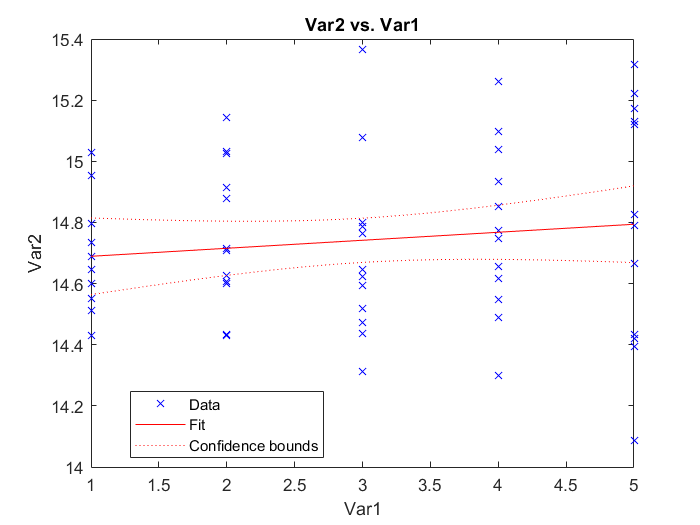


region1 = 0;
for i = 1:5
    for m = 1:12
        region1 = [region1, MSnode_strengths{i,m}(7)];
    end
end
region1 = region1(2:end);

tbl = table(t',region1');
mdl = fitlm(tbl,'linear');
plot(mdl)